% Auto-generated by cameraCalibrator app on 07-Mar-2019
%-------------------------------------------------------


% Define images to process
imageFileNames = {'C:\Users\bengo\Downloads\Photos2\IMG_20190307_162109.jpg',...
    'C:\Users\bengo\Downloads\Photos2\IMG_20190307_162112.jpg',...
    'C:\Users\bengo\Downloads\Photos2\IMG_20190307_162121.jpg',...
    'C:\Users\bengo\Downloads\Photos2\IMG_20190307_162132.jpg',...
    'C:\Users\bengo\Downloads\Photos2\IMG_20190307_162150.jpg',...
    'C:\Users\bengo\Downloads\Photos2\IMG_20190307_162248.jpg',...
    'C:\Users\bengo\Downloads\Photos2\IMG_20190307_162303.jpg',...
    'C:\Users\bengo\Downloads\Photos2\IMG_20190307_163145.jpg',...
    'C:\Users\bengo\Downloads\Photos2\IMG_20190307_163152.jpg',...
    'C:\Users\bengo\Downloads\Photos2\IMG_20190307_163201.jpg',...
    };
% Detect checkerboards in images
[imagePoints, boardSize, imagesUsed] = detectCheckerboardPoints(imageFileNames);

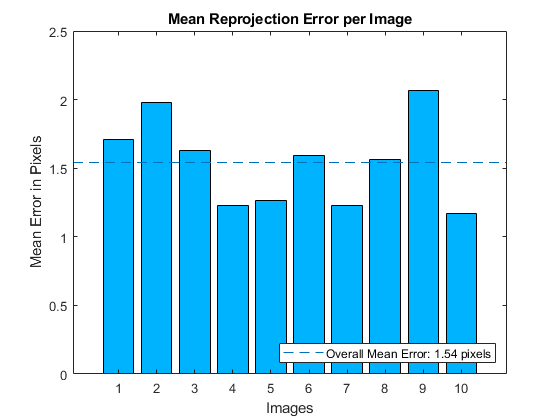

imageFileNames = imageFileNames(imagesUsed);

% Read the first image to obtain image size
originalImage = imread(imageFileNames{1});
[mrows, ncols, ~] = size(originalImage);

% Generate world coordinates of the corners of the squares
squareSize = 20;  % in units of 'millimeters'
worldPoints = generateCheckerboardPoints(boardSize, squareSize);

% Calibrate the camera
[cameraParams, imagesUsed, estimationErrors] = estimateCameraParameters(imagePoints, worldPoints, ...
    'EstimateSkew', false, 'EstimateTangentialDistortion', false, ...
    'NumRadialDistortionCoefficients', 2, 'WorldUnits', 'millimeters', ...
    'InitialIntrinsicMatrix', [], 'InitialRadialDistortion', [], ...
    'ImageSize', [mrows, ncols]);

% View reprojection errors
h1=figure; showReprojectionErrors(cameraParams);


% Visualize pattern locations
h2=figure; showExtrinsics(cameraParams, 'CameraCentric');

% Display parameter estimation errors
displayErrors(estimationErrors, cameraParams);


			Standard Errors of Estimated Camera Parameters
			----------------------------------------------

Intrinsics
----------
Focal length (pixels):   [ 3153.0762 +/- 13.7766    3154.4751 +/- 12.3332 ]
Principal point (pixels):[ 1548.2380 +/- 2.8118     2021.1713 +/- 10.7502 ]
Radial distortion:       [    0.1531 +/- 0.0085       -0.6476 +/- 0.0474  ]

Extrinsics
----------
Rotation vectors:
                         [   -0.2354 +/- 0.0017        0.2695 +/- 0.0017        1.5423 +/- 0.0004  ]
                         [   -0.3846 +/- 0.0017        0.9822 +/- 0.0033        2.1706 +/- 0.0013  ]
                         [   -0.6520 +/- 0.0029       -0.1041 +/- 0.0013        0.6639 +/- 0.0005  ]
                         [   -0.5338 +/- 0.0023        0.7998 +/- 0.0029        1.8635 +/- 0.0011  ]
                         [   -0.3287 +/- 0.0019        0.2364 +/- 0.0016        1.5478 +/- 0.0003  ]
                         [   -0.6874 +/- 0.0026       -0.3884 +/- 0.0017       -0.9063 +/- 0.0006  ]
 

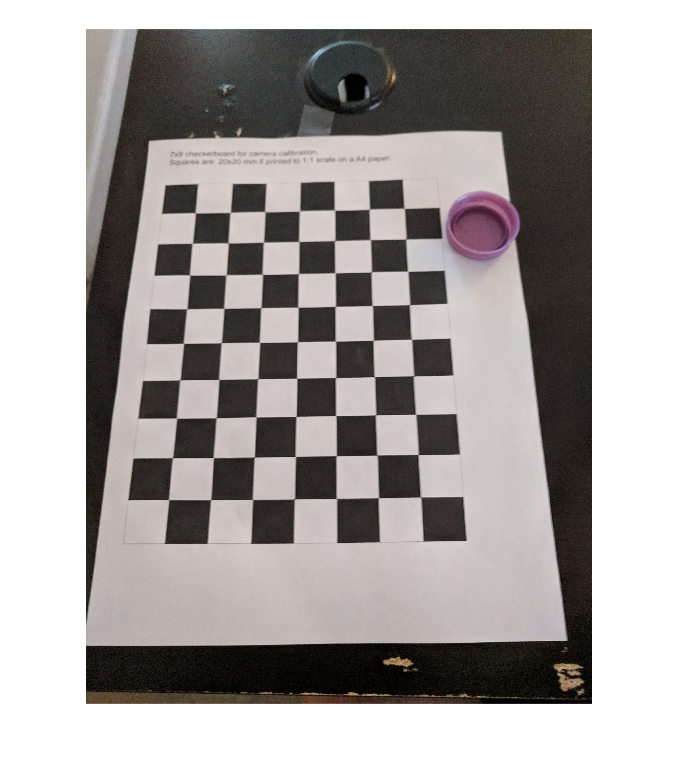


%Check image distortion 
undistortedImage = undistortImage(originalImage, cameraParams);

magnification = 25;
imOrig = imread('C:\Users\bengo\Downloads\Photos2\IMG_20190307_162109.jpg');
figure; imshow(imOrig, 'InitialMagnification', magnification);

title('Input Image');

%Accounting for distortion/ mitigating 
[im, newOrigin] = undistortImage(imOrig, cameraParams, 'OutputView', 'full');
figure; imshow(im, 'InitialMagnification', magnification);

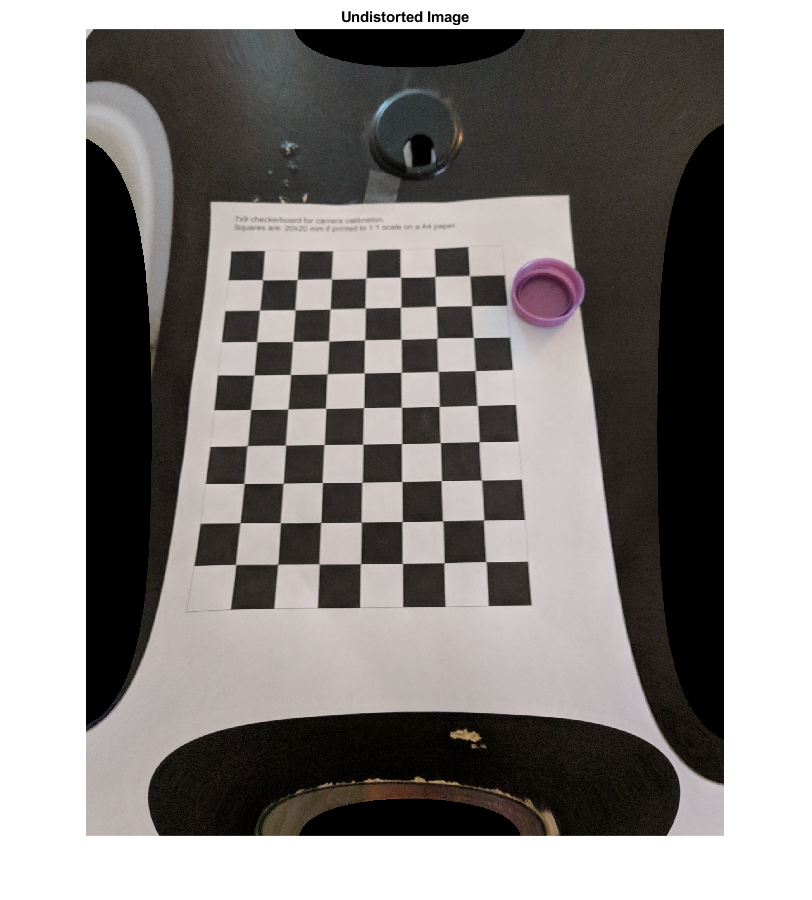

title('Undistorted Image');

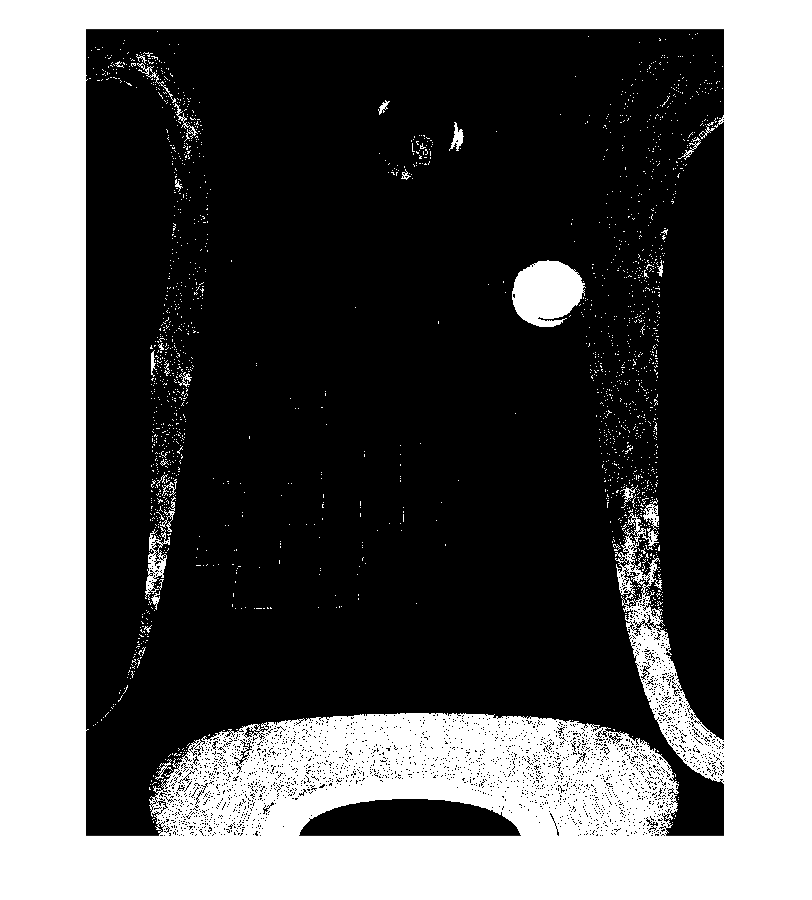


%Convert image to grayscale to get a blob
imHSV = rgb2hsv(im);
saturation = imHSV(:, :, 2);
t = graythresh(saturation);
imCap = (saturation > t);

figure; imshow(imCap, 'InitialMagnification', magnification);


% Find blobs
blobAnalysis = vision.BlobAnalysis('AreaOutputPort', true,...
    'CentroidOutputPort', false,...
    'BoundingBoxOutputPort', true,...
    'MinimumBlobArea', 200, 'ExcludeBorderBlobs', true);
[areas, boxes] = step(blobAnalysis, imCap);

% Sort connected components in descending order by area
[~, idx] = sort(areas, 'Descend');

% Get largest blob
boxes = double(boxes(idx(1:1), :));

% Reduce the size of the image for display
scale = magnification / 100;
imDetectedCap = imresize(im, scale);